ds1=imageDatastore("C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical","IncludeSubfolders",true,"LabelSource","foldernames")

ds1 =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_1.tif';
                              ' ...\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_2939.tif';
                              ' ...\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical\Img_7_5989.tif'
                              }
                     Folders: {
                              'C:\Users\Adarsh Kumar\Desktop\static\srip_prct\elliptical'
                              }
                      Labels: [elliptical; elliptical; elliptical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


img1=readimage(ds1,2)

img1 = 580×780 uint8 matrix
    89    71    71    84   104   135   166   190   204   219   223   233   231   243   243   243   243   223   184   134    97    78    79    92   126   162   199   227   239   243   243   243   237   226   214   179   143   111    82    80    89   120   164   204   237   243   220   173   119    79
    92    88   101   125   157   187   205   220   228   227   225   231   232   243   243   236   224   191   149   107    86    80    92   117   158   191   217   233   234   242   235   230   221   210   180   147   112    85    74    79   103   136   187   221   235   238   215   171   120    80
    94   107   136   167   199   221   231   229   234   223   220   224   230   234   229   220   197   160   123    93    85    91   112   139   180   214   225   228   234   240   234   223   202   183   155   123    87    69    71    88   121   164   204   229   241   230   205   167   123    90
    98   127   165   204   234   243   241   237   227   221   220   

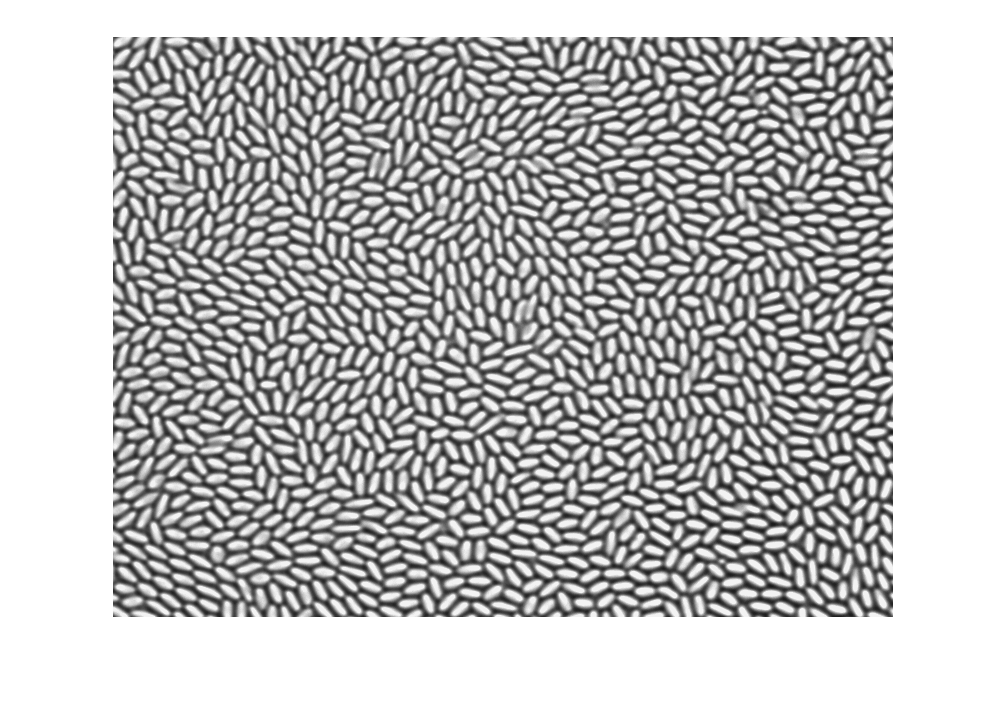

imshow(img1)

img2=img1>150

img2 = 580×780 logical array
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   

cnc=bwconncomp(img2)  

cnc = struct with fields:
    Connectivity: 8
       ImageSize: [580 780]
      NumObjects: 1465
    PixelIdxList: {1×1465 cell}


% bw-binaery worksapce,
% Connected component labeling works by scanning an image, 
% pixel-by-pixel (from top to bottom and left to right) in order to identify connected pixel regions,
% i.e. regions of adjacent pixels which share the same set of intensity values V

rp=regionprops(cnc,"all")

rp = 1465×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


t=linspace(0,2*pi,360)

t =          0    0.0175    0.0350    0.0525    0.0700    0.0875    0.1050    0.1225    0.1400    0.1575    0.1750    0.1925    0.2100    0.2275    0.2450    0.2625    0.2800    0.2975    0.3150    0.3325    0.3500    0.3675    0.3850    0.4025    0.4200    0.4375    0.4550    0.4726    0.4901    0.5076    0.5251    0.5426    0.5601    0.5776    0.5951    0.6126    0.6301    0.6476    0.6651    0.6826    0.7001    0.7176    0.7351    0.7526    0.7701    0.7876    0.8051    0.8226    0.8401    0.8576


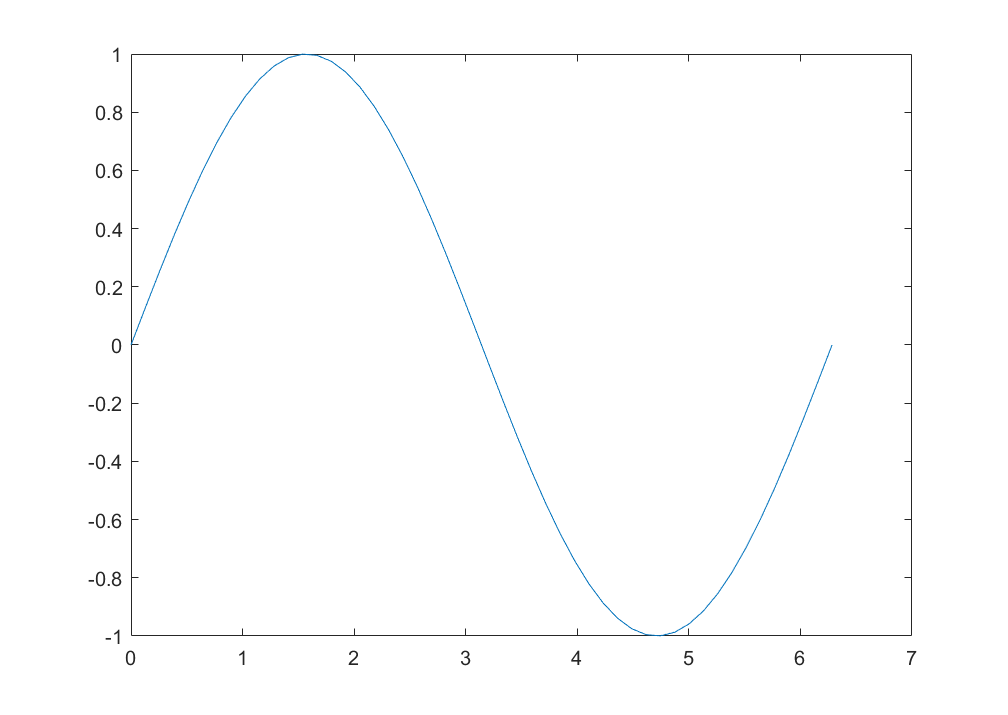

plot(t,sin(t))

for i=1:length(rp)
    print("
end

String is not terminated properly.